load("C:\Users\Muriate_C\Desktop\ECE 271A\HW2\TrainingSamplesDCT_8_new.mat")
BG = TrainsampleDCT_BG;
FG = TrainsampleDCT_FG;

% Compute priors using MLE
c_fg = size(FG, 1);
c_bg = size(BG, 1);
n = c_fg + c_bg;
prob_bg = c_bg / n;
prob_fg = c_fg / n;

ZigZagPattern = readmatrix("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\Zig-Zag Pattern.txt");
ZigZagPattern = ZigZagPattern + 1;
ZigZagPattern = int8(ZigZagPattern);

img = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah.bmp");
img = im2double(img);

% Zero Padding
% right = zeros(255, 7);
% bottom = zeros(7, 277);
% img_pad = [[img right]; bottom];
left = zeros(255, 4);
right = zeros(255, 3);
up = zeros(4, 277);
bottom = zeros(3, 277);
img_pad = [up; [left img right]; bottom];

% DCT
% img_dct = dct_8(img, img_pad);
img_dct = dct_8(img);

% ZigZag Scan
img_scan = blockproc(img_dct, [8 8], @(block_struct) ZigZagScan(block_struct.data, ZigZagPattern));

ground_truth = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah_mask.bmp");
ground_truth = im2double(ground_truth);

n_mixtures = 1;
dims = [1 2 4 8 16 24 32 40 48 56 64];
n_componets = [1 2 4 8 16 32];

mu_bg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
sigma_bg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
pi_bg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
mu_fg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
sigma_fg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
pi_fg_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');
poe_list_dict = containers.Map('KeyType', 'uint32', 'ValueType','any');

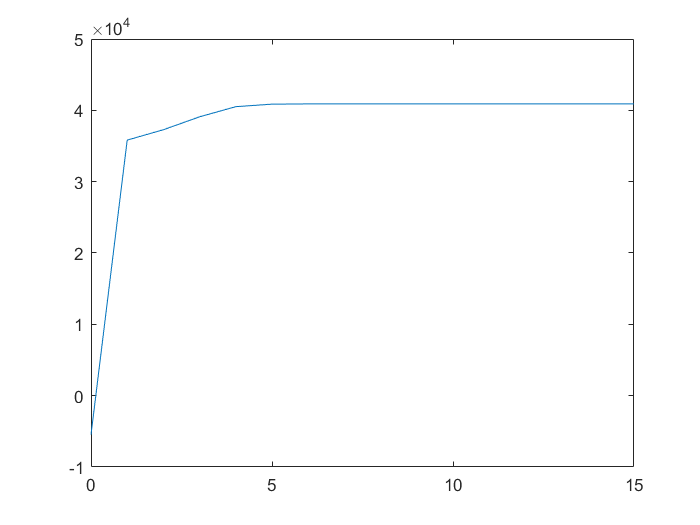

% generate GMM parameters using EM
for c = n_componets%(1, 4)
    clf;
    mu_bg_c = zeros(c, 64, n_mixtures);
    sigma_bg_c = zeros(64, 64, c, n_mixtures);
    pi_bg_c = zeros(n_mixtures, c);
    mu_fg_c = zeros(c, 64, n_mixtures);
    sigma_fg_c = zeros(64, 64, c, n_mixtures);
    pi_fg_c = zeros(n_mixtures, c);
    for i_BG = 1:n_mixtures
        [mu_bg, sigma_bg, pi_bg] = EM(BG, c, 200);
        mu_bg_c(:, :, i_BG) = mu_bg;
        sigma_bg_c(:, :, :, i_BG) = sigma_bg;
        pi_bg_c(i_BG, :) = pi_bg;
    end
    mu_bg_dict(c) = mu_bg_c;
    sigma_bg_dict(c) = sigma_bg_c;
    pi_bg_dict(c) = pi_bg_c;
    for i_FG = 1:n_mixtures
        [mu_fg, sigma_fg, pi_fg] = EM(FG, c, 200);
        mu_fg_c(:, :, i_FG) = mu_fg;
        sigma_fg_c(:, :, :, i_FG) = sigma_fg;
        pi_fg_c(i_FG, :) = pi_fg;
    end
    mu_fg_dict(c) = mu_fg_c;
    sigma_fg_dict(c) = sigma_fg_c;
    pi_fg_dict(c) = pi_fg_c;
end

% Classification
for c = n_componets%(1, 4)
    i = find(n_componets==c);
    disp(join(['clf ', int2str(i)])); 
    mu_bg_all = mu_bg_dict(c);
    sigma_bg_all = sigma_bg_dict(c);
    pi_bg_all = pi_bg_dict(c);
    mu_fg_all = mu_fg_dict(c);
    sigma_fg_all = sigma_fg_dict(c);
    pi_fg_all = pi_fg_dict(c);
    poe_list = zeros(n_mixtures, size(dims, 2), n_mixtures);
    for i_BG = 1:n_mixtures
        for i_FG = 1:n_mixtures
%             disp(join(['clf ', int2str((i_BG-1)*5+i_FG)])); 
            mu_bg = mu_bg_all(:, :, i_BG);
            sigma_bg = sigma_bg_all(:, :, :, i_BG);
            pi_bg = pi_bg_all(i_BG, :);
            mu_fg = mu_fg_all(:, :, i_FG);
            sigma_fg = sigma_fg_all(:, :, :, i_FG);
            pi_fg = pi_fg_all(i_FG, :);
            for i_dim = 1:size(dims, 2)
                dim = dims(i_dim);
                mu_bg_d = mu_bg(:, 1:dim);
                sigma_bg_d = sigma_bg(1:dim, 1:dim, :);
                mu_fg_d = mu_fg(:, 1:dim);
                sigma_fg_d = sigma_fg(1:dim, 1:dim, :);
                
                mask = blockproc(img_scan, [1, 64], @(block_struct) mixBDR(block_struct.data(1, 1:dim), ...,
                    c, mu_bg_d, mu_fg_d, sigma_bg_d, sigma_fg_d, pi_bg, pi_fg, prob_bg, prob_fg));
                mask = [[mask zeros(248, 7)]; zeros(7, 270)];
                poe_list(i_BG, i_dim, i_FG) = P_Error(ground_truth, mask, prob_bg, prob_fg);
            end
            poe_list(i_BG, :, i_FG)
        end
    end
    poe_list_dict(c) = poe_list;
end

clf 1


ans =     0.0629    0.0640    0.0624    0.0657    0.0654    0.0664    0.0746    0.0774    0.0809    0.0843    0.0852


clf 2


ans =     0.0620    0.0630    0.0556    0.0584    0.0513    0.0522    0.0573    0.0596    0.0611    0.0621    0.0630


clf 3


ans =     0.0623    0.0631    0.0605    0.0635    0.0523    0.0498    0.0505    0.0501    0.0494    0.0499    0.0501


clf 4


ans =     0.0619    0.0631    0.0609    0.0633    0.0551    0.0534    0.0530    0.0526    0.0516    0.0523    0.0526


clf 5


ans =     0.0623    0.0616    0.0607    0.0657    0.0564    0.0543    0.0560    0.0561    0.0552    0.0560    0.0560


clf 6


ans =     0.0628    0.0629    0.0600    0.0659    0.0580    0.0516    0.0503    0.0504    0.0513    0.0521    0.0524


% Plot for the 25 classifiers
for c = n_componets(1, 4)
    poe_list = poe_list_dict(c);
%     load("poe25.mat");
    for i_bg = 1:n_mixtures
        f = figure(i_bg);
        clf;
        hold on;
        l1 = plot(dims, poe_list(i_bg, :, 1), 'LineWidth', 1);
        l2 = plot(dims, poe_list(i_bg, :, 2), 'LineWidth', 1);
        l3 = plot(dims, poe_list(i_bg, :, 3), 'LineWidth', 1);
        l4 = plot(dims, poe_list(i_bg, :, 4), 'LineWidth', 1);
        l5 = plot(dims, poe_list(i_bg, :, 5), 'LineWidth', 1);
        
        for i = 1:length(dims)
            xline(dims(i), '--')
        end
        xticks(dims);
        title(join(["Background Mixture", int2str(i_bg), "with 5 Different Foreground Mixtures"]))
        xlabel("Dimensions")
        ylabel("Probability of Error")
        legend([l1, l2, l3, l4, l5], 'FG Mixture 1', 'FG Mixture 2', 'FG Mixture 3', ...,
            'FG Mixture 4', 'FG Mixture 5', 'Location', 'northeast')
        exportgraphics(f, append('5-1-', int2str(i_bg), '.png'));
    end
end

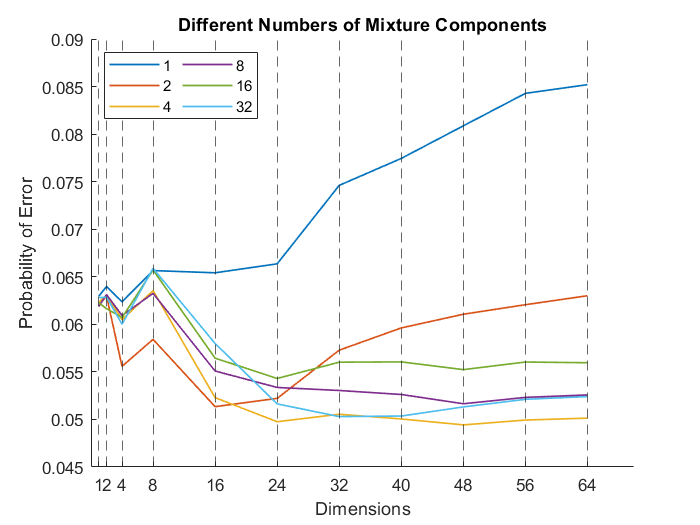

% Plot for the 6 classifiers
colors = ['y', 'c', 'r', 'b', 'g', 'm'];
f = figure;
for c = n_componets
    i = find(n_componets==c);
    poe_list = poe_list_dict(c);
    plot(dims, poe_list, 'LineWidth', 1);
    hold on;    
    
    legend_str{i} = int2str(c);
end

for j = 1:length(dims)
    xline(dims(j), '--')
end
box off;
xticks(dims);
title("Different Numbers of Mixture Components");
xlabel("Dimensions")
ylabel("Probability of Error")
lgd = legend(legend_str, 'Location', 'northwest');
lgd.NumColumns = 2;
exportgraphics(f, '5-2.png');

function [mu, sigma, pi_z] = EM(sample, c, n_iter)
    % initialize mu, sigma, pi
%     mu = randn(c, 64);
    mu = sample(randperm(size(sample, 1), c), :);
    sigma = zeros(64, 64, c);
    sigma_diag = rand(c, 64);
    for i = 1:c
        sigma(:, :, i) = diag(sigma_diag(i, :));
    end
    pi_z = ones(1, c) / c;
    H = zeros(size(sample, 1), c);
    epsilon = diag(1e-6*ones(1, 64));
    
    % track the log-likelihood for stopping the iteration
    ll = loglikelihood(sample, mu, sigma, pi_z);
    ll_track = [ll];
    threshold = 1e-4;
    iters = [0];
    
    for iter = 1:n_iter
        iters = [iters, iter];
        % E-step
        for i = 1:size(sample, 1)
            for k = 1:c
                H(i, k) = mvnpdf(sample(i, :), mu(k, :), sigma(:, :, k)) * pi_z(k);
            end
            H(i, :) = H(i, :) / sum(H(i, :));
        end
        % M-step
        sigma_new = zeros(64, 64, c);
        for j = 1:c
            mu(j, :) = sum(H(:, j).*sample) / sum(H(:, j));
            for i = 1:size(sample, 1)
                tmp = (sample(i, :) - mu(j, :)).'*(sample(i, :) - mu(j, :));
                sigma_new(:, :, j) = sigma_new(:, :, j) + H(i, j) * diag(diag(tmp));
            end
            sigma_new(:, :, j) = sigma_new(:, :, j) / sum(H(:, j)) + epsilon;
            pi_z(j) = sum(H(:, j)) / size(sample, 1);  
        end
        sigma = sigma_new;
        
        ll_new = loglikelihood(sample, mu, sigma, pi_z);
        ll_track = [ll_track, ll_new];
        % stop the iteration if the increment is less than the threshold
        if (ll_new - ll) < threshold
            break
        end
        ll = ll_new;
        plot(iters, ll_track)
        drawnow();
    end
end

function vector = ZigZagScan(matrix, pattern)
    vector = zeros(1, size(matrix, 1) * size(matrix, 2));
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            position = pattern(i, j);
            vector(1, position) = matrix(i, j);
        end
    end
end

% function dct = dct_8(img, img_pad)
%     dct = zeros(size(img, 1) * 8, size(img, 2) * 8);
%     for i = 1:size(img, 1)
%         for j = 1:size(img, 2)
%             dct((8*i-7):(8*i), (8*j-7):(8*j)) = dct2(img_pad(i:i+7, j:j+7));
%         end
%     end
% end

function dct = dct_8(img)
    dct = zeros((size(img, 1) - 7) * 8, (size(img, 2) -7) * 8);
    for i = 1:(size(img, 1)-7)
        for j = 1:(size(img, 2)-7)
            dct((8*i-7):(8*i), (8*j-7):(8*j)) = dct2(img(i:i+7, j:j+7));
        end
    end
end

% function density = mvnpdf(x, mu, sigma)
%     k = size(x, 2);
%     density = (2*pi).^(-k/2) / sqrt(det(sigma)) * exp(-(x-mu)*inv(sigma)*(x-mu).'/2);
% end

function ll = loglikelihood(sample, mu, sigma, pi)
    ll = 0;
    for i = 1:size(sample, 1)
        ll_x = 0;
        for j = 1:size(mu, 1)
            ll_x = ll_x + pi(1, j) * mvnpdf(sample(i, :), mu(j, :), sigma(:, :, j));
        end
        ll = ll + log(ll_x);
    end
end

function mask = mixBDR(feature, c, mu_bg, mu_fg, sigma_bg, sigma_fg, pi_bg, pi_fg, P_bg, P_fg)
    p_x_bg = 0;
    p_x_fg = 0;
    for i = 1:c
        p_x_bg = p_x_bg + pi_bg(1, i) * mvnpdf(feature, mu_bg(i, :), sigma_bg(:, :, i));
        p_x_fg = p_x_fg + pi_fg(1, i) * mvnpdf(feature, mu_fg(i, :), sigma_fg(:, :, i)); 
    end
    if p_x_bg * P_bg > p_x_fg * P_fg
        mask = 0;
    else
        mask = 1;
    end
end

function p = P_Error(gt, mask, prob_bg, prob_fg)
    gt = int8(gt);
    mask = int8(mask);
    diff = gt - mask;
    detect = 1 - sum(sum(diff==1))/sum(sum(gt==1));
    fAlarm = sum(sum(diff==-1))/sum(sum(gt==0));
    p = fAlarm * prob_bg + (1 - detect) * prob_fg;
end